# Final Project

## Infor infor

xxx-xxx-xxx

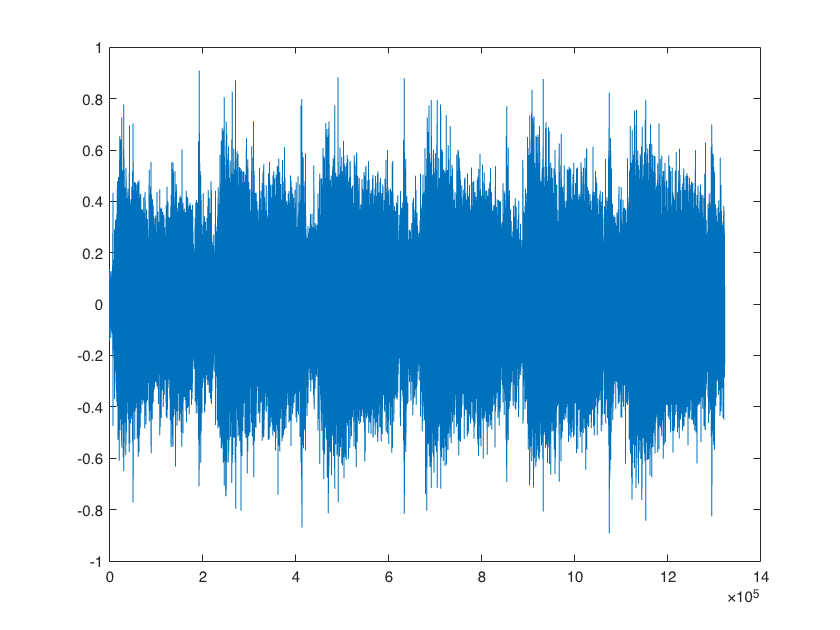

[x,fs] = audioread('../noisy.wav');
plot(x);

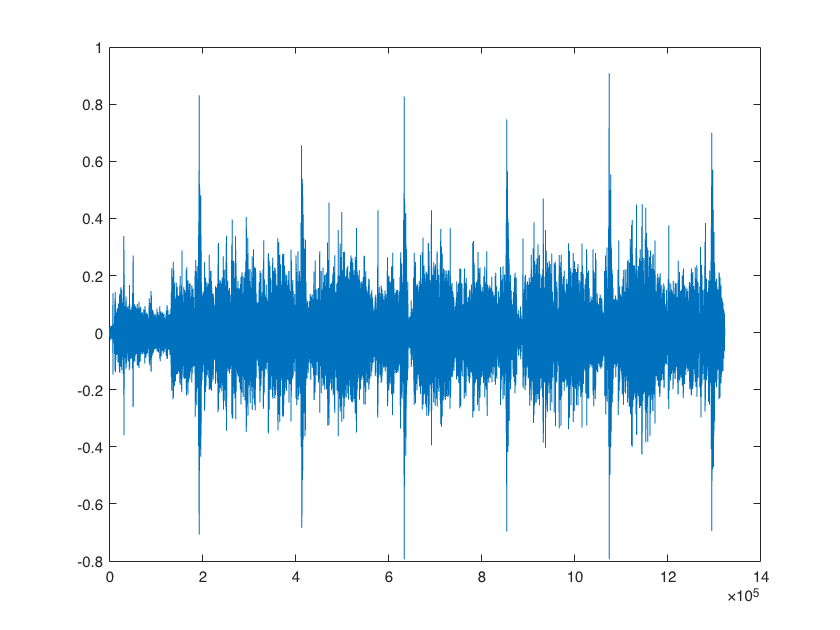

xhat = denoise(x, fs);
plot(xhat);

[cleanSig, fs] = audioread('../clean.wav');
result_snr = computeSnr(cleanSig, xhat)

ans = 2.0776

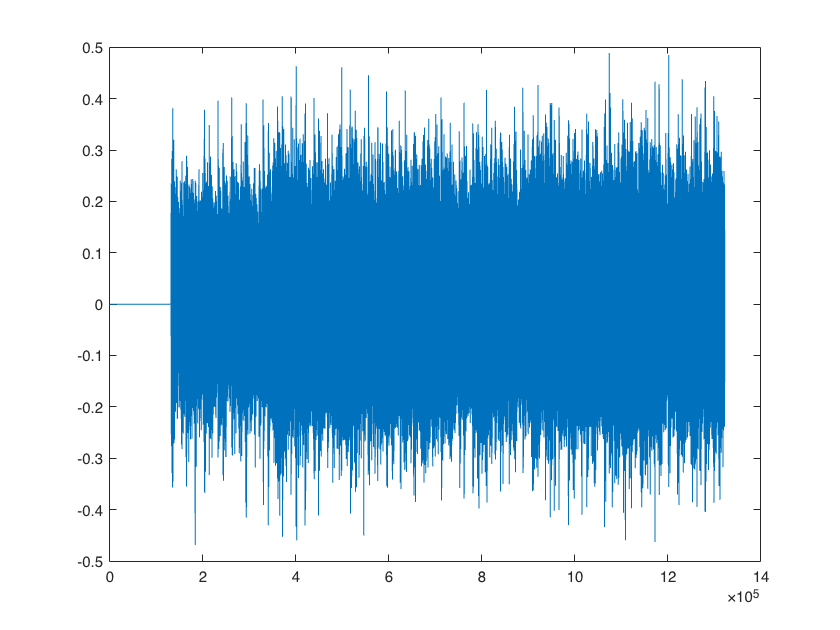

plot(cleanSig);

### Evaluate

exp_name = 'test';
data = result_snr;
filename = './results.txt';
evaluate(filename, exp_name, result_snr, x, xhat)